# S3

Donat un filtre H que no està normalitzat. Quina seria l'expressió de Matlab, en una línia, que normalitzaria la matriu H i deixaria el resultat en la mateixa matriu H? (sense espais en la resposta)

Per exemple, la matriu següent:

     1     2     3

     4     5     6

     7     8     9

Quedaria normalitzada tal que:

    0.0222    0.0444    0.0667

    0.0889    0.1111    0.1333

    0.1556    0.1778    0.2000

H = [1, 2, 3;
     4, 5, 6;
     7, 8, 9]

H =      1     2     3
     4     5     6
     7     8     9


H = H / sum(sum(H))

H =     0.0222    0.0444    0.0667
    0.0889    0.1111    0.1333
    0.1556    0.1778    0.2000


Quin filtre s'ha utilitzat en el següent script per obtenir el resultat de la figura mostrada? Dos filtres donen un resultat similar, un d'ells és el correcte, però les diferències són molt subtils...

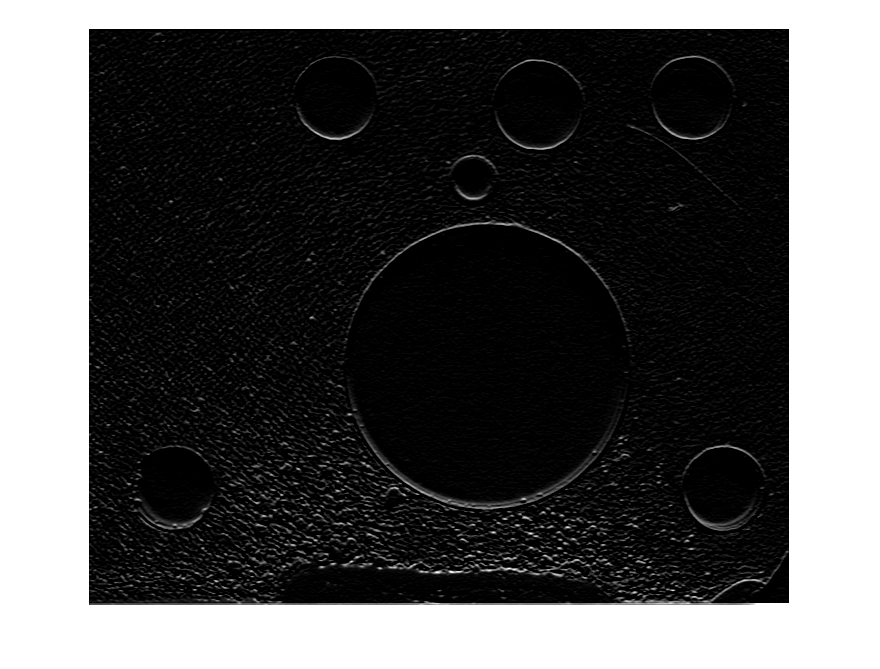

A = imread('Turbo.tif');
h = fspecial('prewitt');
B = imfilter(A,h);
imshow(B);

En la propera imatge es veu la importància de treballar amb el tipus de dades correcte. En aquest cas, s'ha utilitzat el tipus int8 per calcular els gradients (verticals)i els resultats milloren en relació a utilitzar el tipus uint8. La pregunta és: q

Quins contorns (positius/negatius/horitzontals/tots/cap) desapareixen al realitzar el mateix calcul però utilitzant uint8.

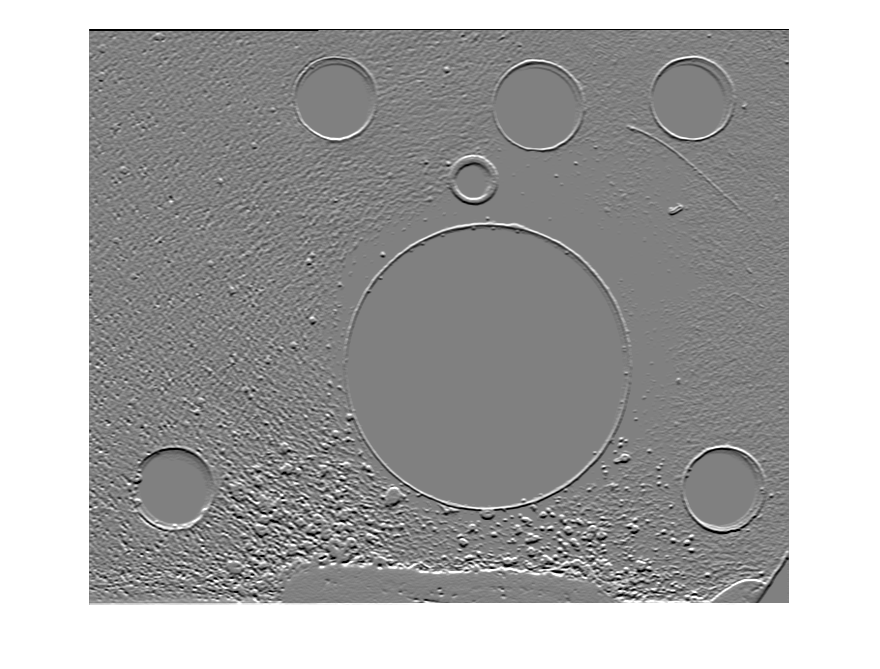

A = imread('Turbo.tif');
h = fspecial('prewitt');
B = imfilter(int8(A),h);
imshow(B,[]);

Quin tipus de filtre és el següent filtre? integratiu, derivatiu, prewitt, sobel o cap dels anteriors

h = 1/32*[3 5 5 3; 0 0 0 0; 3 5 5 3];

El següent script detecta els gradients que estan aproximadament a 45º. Quina és la instrucció indicada amb XXXXX?

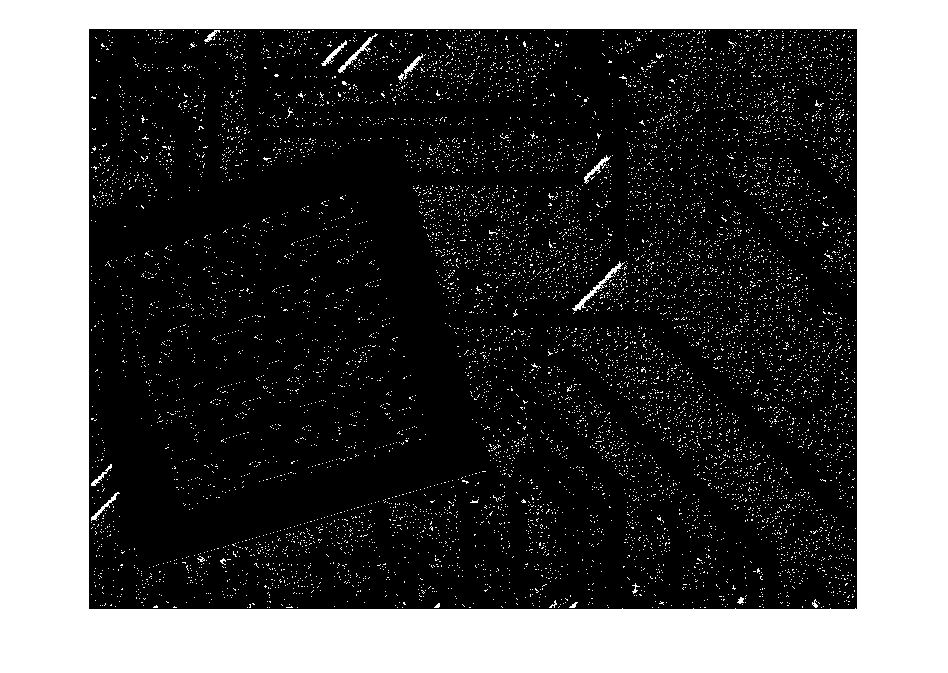

A = imread('Label 5.tif');
hv = fspecial('sobel');
hh = hv';
V = imfilter(double(A),hv);
H = imfilter(double(A),hh);
%   C = abs(V.*V+H.*H);
O = atan2(V,H);
C45 = abs(O - pi/4) < 0.1;
imshow(C45,[]);

Quin és el valor de la variable X que proporciona una imatge com la que es mostra detallada a continuació?

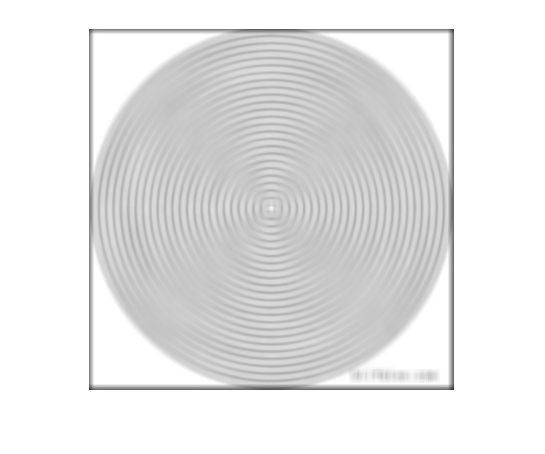

A = imread('Concentric Circles.jpg');
h = fspecial('average',10);
V = imfilter(A,h);
imshow(V);

Quants píxels de contorn es mostren en la següent imatge, extreta amb el codi que s'indica a continuació?

A = imread('Pin 1.jpg');
E = edge(A,'Canny',0.5,sqrt(2));
C = sum(sum(E == 1))

C = 11316

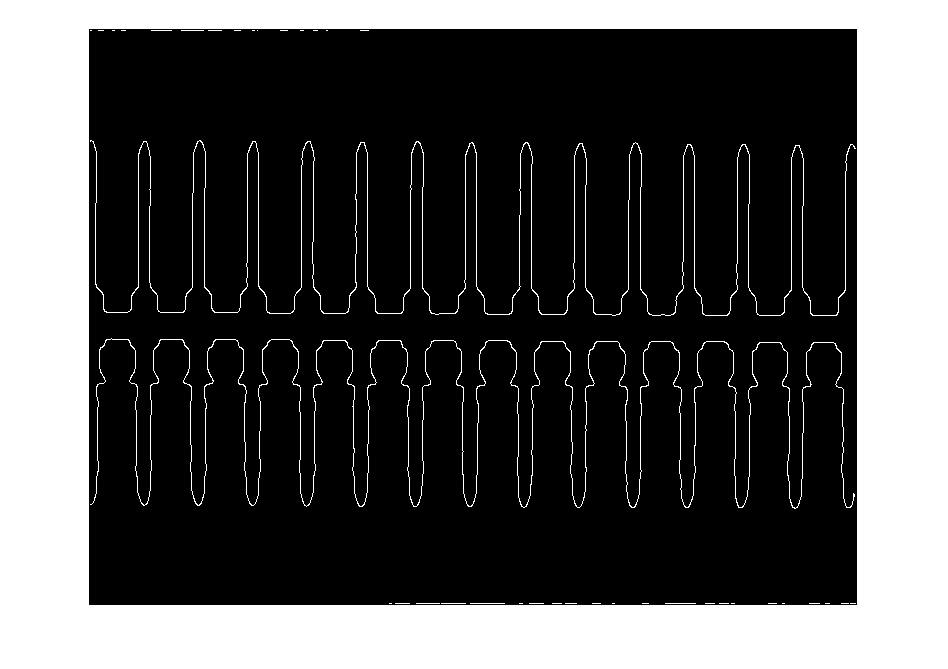

imshow(E);

Quina mida té la finestra del filtre no lineal que s'aplica a continuació?

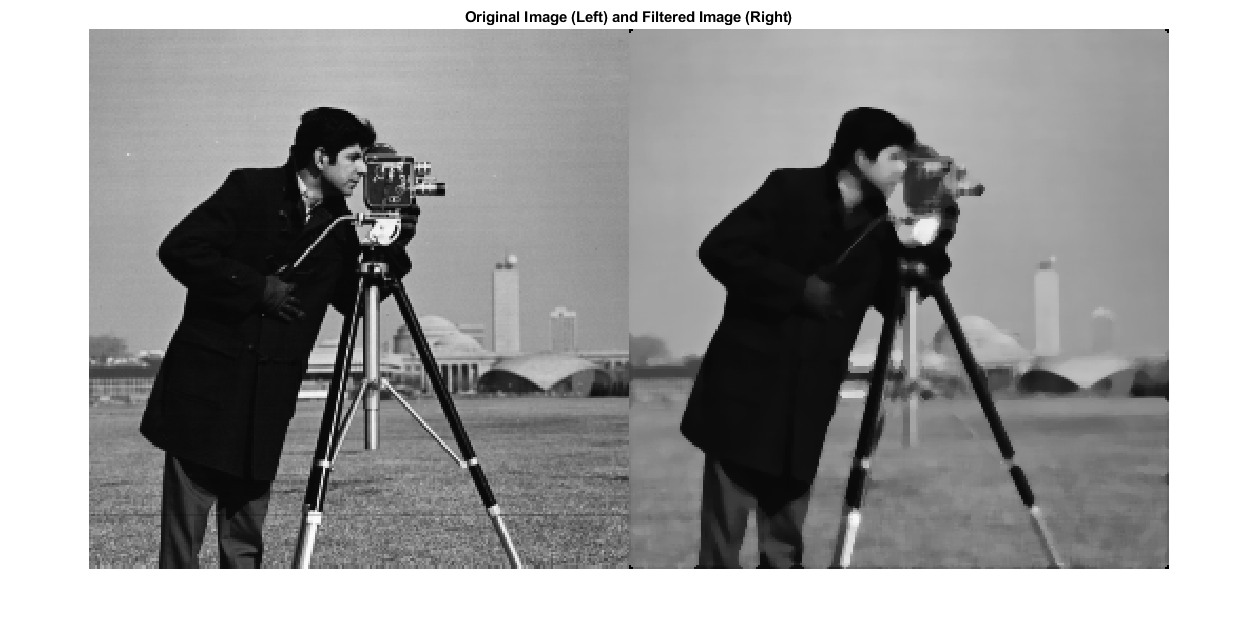

A = imread('cameraman.tif');
fun = @(x) median(x(:));
B = nlfilter(A,[5 5],fun);
montage({A,B})
title('Original Image (Left) and Filtered Image (Right)')

Mentalment, quin valor obtindrem en executar el següent script?

A = int8(imread('cameraman.tif'));
h1 = [1 2 1];
h2 = [1 0 -1]';
s = h2*h1;
A1 = imfilter(A,h2);
A2 = imfilter(A1,h1);
S = imfilter(A,s);
sum(sum(A2-S))

ans = 0

Quina imatge dona una millor impressió visual? R/RNF/indiferent

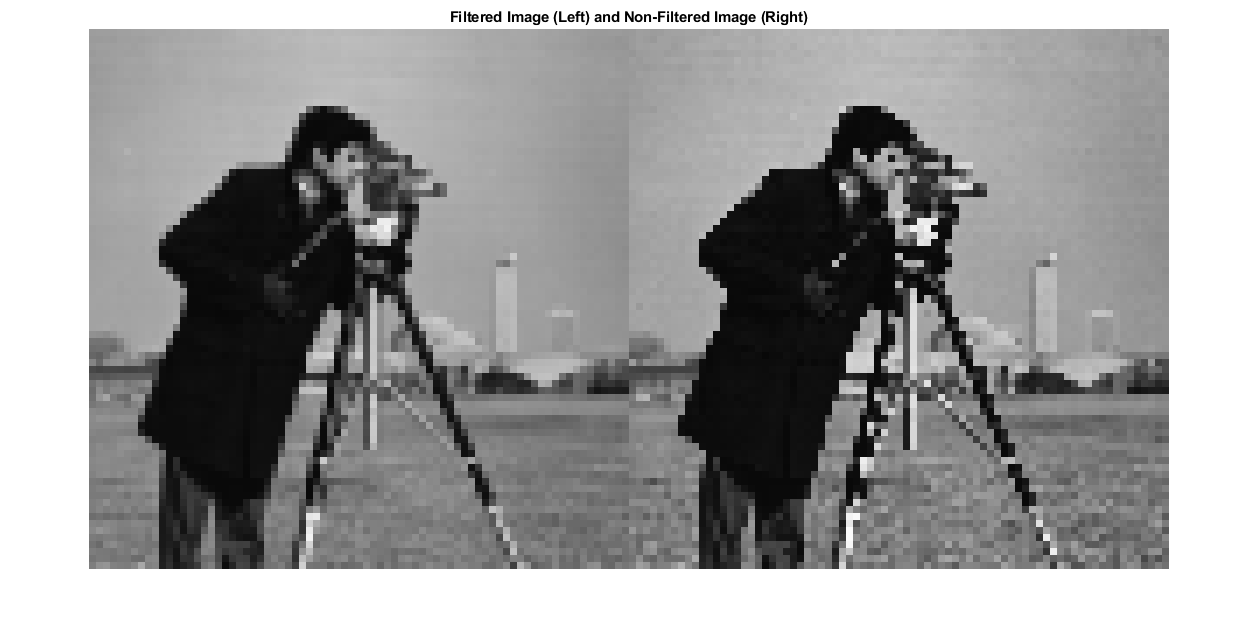

close all
A = imread('cameraman.tif');
F = imgaussfilt(A,2,'FilterSize',3);
R = imresize(F,0.3,'nearest');
RNF = imresize(A,0.3,'nearest');
montage({R,RNF})
title('Filtered Image (Left) and Non-Filtered Image (Right)')